## Transducer modelling:

 **Sittig Transfer matrix:**

clear all
x=0.0000042;


## variables

w=linspace(2*pi*5*10^5,2*pi*10^7,2*10000)   % System angular frequency in rad/s

w = 	1.0e+07 *

    0.3142    0.3145    0.3148    0.3151    0.3154    0.3157    0.3160    0.3162    0.3165    0.3168    0.3171    0.3174    0.3177    0.3180    0.3183    0.3186    0.3189    0.3192    0.3195    0.3198    0.3201    0.3204    0.3207    0.3210    0.3213    0.3216    0.3219    0.3222    0.3225    0.3228    0.3231    0.3234    0.3237    0.3240    0.3243    0.3246    0.3249    0.3252    0.3255    0.3258    0.3261    0.3264    0.3267    0.3270    0.3273    0.3276    0.3279    0.3282    0.3285    0.3288



a=2.5*10^-3;                     % Radius of the piezoelectric plate
rho=7.8*10^3;                    % Piezoelectric plate density
c_33=16.6*10^10;                 % Elastic constant of the plate
d=2*10^-3;                       % plate thickness
Z_b=x*w                         % Acoustic impedance of the backing plate (this is a function of frequency)

Z_b =    13.1947   13.2072   13.2198   13.2323   13.2448   13.2574   13.2699   13.2824   13.2950   13.3075   13.3200   13.3326   13.3451   13.3577   13.3702   13.3827   13.3953   13.4078   13.4203   13.4329   13.4454   13.4579   13.4705   13.4830   13.4955   13.5081   13.5206   13.5331   13.5457   13.5582   13.5708   13.5833   13.5958   13.6084   13.6209   13.6334   13.6460   13.6585   13.6710   13.6836   13.6961   13.7086   13.7212   13.7337   13.7463   13.7588   13.7713   13.7839   13.7964   13.8089


d_33=265*10^-12;                 % Piezoelectric charge coefficient
s_33=14.2*10^-12;                % Elastic compliance coefficient
epsilon_0=8.854*10^-12;          % Vacuum permitivity
epsilon_33=1200*epsilon_0;       % relativity Permativity
Beta_33= epsilon_0/epsilon_33;   % the dielectric impermeability of the plate at constant strain,
c=1300;                          % compresisonal wave speed in fluid                     
h_33= d_33/(s_33*epsilon_33);    % Piezoelectric stiffness constant for the plate
v_o=sqrt(c_33/rho);              % compressional wave speed from piezoelectric
k=w/v_o                         % wave number for the peizoelectric plate

k = 	1.0e+04 *

    0.0681    0.0682    0.0682    0.0683    0.0684    0.0684    0.0685    0.0686    0.0686    0.0687    0.0687    0.0688    0.0689    0.0689    0.0690    0.0691    0.0691    0.0692    0.0693    0.0693    0.0694    0.0695    0.0695    0.0696    0.0697    0.0697    0.0698    0.0698    0.0699    0.0700    0.0700    0.0701    0.0702    0.0702    0.0703    0.0704    0.0704    0.0705    0.0706    0.0706    0.0707    0.0708    0.0708    0.0709    0.0709    0.0710    0.0711    0.0711    0.0712    0.0713


S=pi*a^2;                        % Piezoelectric surface area
C_o=S/(Beta_33*d);               % the clamped capacitance of the plate
n=h_33*C_o;                      % A given constant
S_a=S;                           % effective face area of the transducer
rho_2=857;                       % density of the fluid
Kin_Vis=32*10^-6;                % Kinematic Viscosity of the fluid (ISO VG 32)
Vis=Kin_Vis*rho_2;               % Dynamic viscosity of the fluid

Z_o=rho*v_o*S;                   % plane wave acoustic impedance of the piezoelectric plate
c_2=3230;                        %Speed of sound in steel
rho_3=7850;                      %Density of steel
R=((c*rho_2)-(c_2*rho_3))/((c*rho_2)+(c_2*rho_3)); %Reflection coefficient 
L=0.00448;                        %Lentgh of chamber


## Matrix equations




TAe_matrix = zeros(length(w),1);
TAa_matrix = zeros(length(w),1);
TA_matrix = zeros(length(w),1);

for p=1:length(w)
    
    steps1 = 2*p - 1;
    steps2 = 2*p;
    
TAe_matrix(steps1:steps2,1:2) =[1/n n/(1i*w(p)*C_o); -1i*w(p)*C_o 0];         %Transducer electrical matrix
TAa_matrix(steps1:steps2,1:2) =(1/(Z_b(p)-1i*Z_o*tan((k(p))*d/2)))*[Z_b(p)+1i*Z_o*cot(k(p)*d) (Z_o)^2+1i*Z_o*Z_b(p)*cot(k(p)*d); 1 Z_b(p)-2*1i*Z_o*tan(k(p)*d/2)];     %Transducer acoustic matrix

TA_matrix(steps1:steps2,1:2) = TAe_matrix(steps1:steps2,1:2)*TAa_matrix(steps1:steps2,1:2); %Sittig model matrix



end




**Solving for sensitivity **$S_{\textrm{vI}}$**:**

Z_r=S_a*rho_2*c;         % Acoustic radiation impedance

S_vI = zeros(length(w),1);

for kl = 1:length(w)
    
    ste2 = 2*kl;
  S_vI(kl)=1/(Z_r*TA_matrix(ste2,1)+TA_matrix(ste2,2)); %Sensitivity for vI.  
end


**Transducer electrical impedance :**

Z_in = zeros(length(w),1);

for wen = 1:length(w)
ste3 = 2*wen-1;
ste4 = 2*wen;
Z_in(wen) =(Z_r*TA_matrix(ste3,1)+TA_matrix(ste3,2))/(Z_r*TA_matrix(ste4,1)+TA_matrix(ste4,2)); %Electrical impedance of the transducer
end

**Final transfer function **$S_{\textrm{FV}}$**:**

S_FV = zeros(length(w),1)

S_FV =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0



for phi = 1:length(w)
 S_FV(phi) =Z_r*S_vI(phi)/Z_in(phi); %Sensitivity FV  
end

S_FV_DB=20*log10(abs(S_FV))

S_FV_DB =   -34.1730
  -34.1648
  -34.1565
  -34.1483
  -34.1401
  -34.1318
  -34.1236
  -34.1154
  -34.1072
  -34.0990


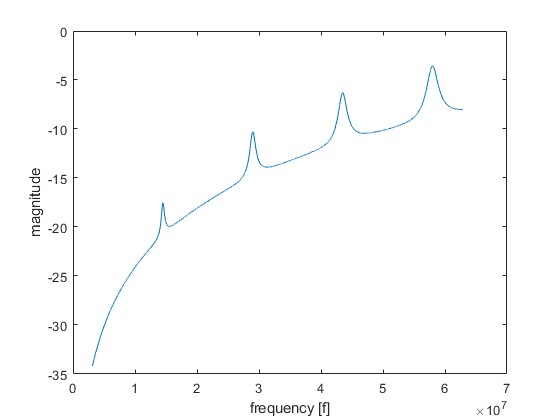


plot(w,S_FV_DB)
xlabel('frequency [f]')
ylabel(['magnitude'])